% Using edfread
route = 'chb01_01.edf'

route = 'chb01_01.edf'

[data, header] = edfread(route);



disp(data.Properties.VariableNames);

    {'SignalLabel1_FP1_F7'}    {'SignalLabel2_F7_T7'}    {'SignalLabel3_T7_P7'}    {'SignalLabel4_P7_O1'}    {'SignalLabel5_FP1_F3'}    {'SignalLabel6_F3_C3'}    {'SignalLabel7_C3_P3'}    {'SignalLabel8_P3_O1'}    {'SignalLabel9_FP2_F4'}    {'SignalLabel10_F4_C4'}    {'SignalLabel11_C4_P4'}    {'SignalLabel12_P4_O2'}    {'SignalLabel13_FP2_F8'}    {'SignalLabel14_F8_T8'}    {'SignalLabel15_T8_P8'}    {'SignalLabel16_P8_O2'}    {'SignalLabel17_FZ_CZ'}    {'SignalLabel18_CZ_PZ'}    {'SignalLabel19_P7_T7'}    {'SignalLabel20_T7_FT9'}    {'SignalLabel21_FT9_FT10'}    {'SignalLabel22_FT10_T8'}    {'SignalLabel23_T8_P8'}



all_data = cell2mat(table2cell(data));

% Normalize Data
normalizedData = normalize(all_data,"range");


time_frame = [0,6];

wanted_data = normalizedData((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);

m = 4;
t = 14;
num_channels = size(wanted_data, 2);  % Number of columns (channels)
epsilon = std(wanted_data);

% Run once to get the size of an RM (assuming fixed size)
sample_rm = computeRM_blockedkronecker_nonsymmetric(wanted_data(:, 1), m, t, 50, 1.8);
% Preallocate a logical 3D array (fastest)
[N, M] = size(sample_rm);  % Get matrix size
recurrence_matrices = false(N, M, num_channels);

% Compute recurrence matrices in a loop
for i = 1:num_channels
    recurrence_matrices(:, :, i) = computeRM_blockedkronecker_nonsymmetric(wanted_data(:, i), m, t, 29, 1.8)<(0.3);
end


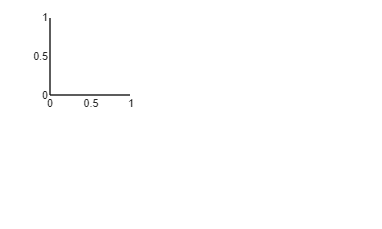


treshold_matrix = all(recurrence_matrices,3);

subplot(2,3,1);

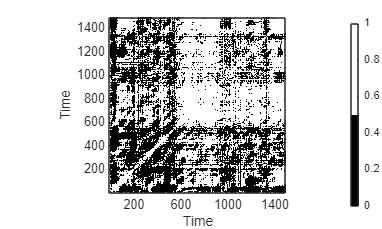

figure('Position', [100, 42, 1000, 600]);
colormap([0 0 0 ; 1 1 1]);

imagesc(treshold_matrix);
xlabel('Time');
ylabel('Time');
axis xy
axis tight
axis square
colorbar('Location', 'east', 'Position', [0.92, 0.1, 0.02, 0.8]);

disp(recurrence_matrices(:,:,1))

   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0